# Planteamiento de una trayectoria de un elipse

Planteamiento de las ecuaciones en el plano

syms e_p x_c theta_e A B y_c T_elip

e_p = [x_c+A*cos(theta_e);y_c+B*sin(theta_e);0]

$$e\_p = \left(\begin{array}{c} x_{c}+A\,\cos\left(\theta_{e}\right)\\ y_{c}+B\,\sin\left(\theta_{e}\right)\\ 0 \end{array}\right)$$


T_elip =[1 0 0 x_c+A*cos(theta_e);0 1 0 y_c+B*sin(theta_e);0 0 1 0;0 0 0 1]

$$T\_elip = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{c}+A\,\cos\left(\theta_{e}\right)\\ 0 & 1 & 0 & y_{c}+B\,\sin\left(\theta_{e}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Planteamiento de manera general 

syms T_tran x_t y_t z_t

T_tran =[1 0 0 x_t;0 1 0 y_t;0 0 1 z_t;0 0 0 1]

$$T\_tran = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{t}\\ 0 & 1 & 0 & y_{t}\\ 0 & 0 & 1 & z_{t}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_elip*T_tran

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{c}+x_{t}+A\,\cos\left(\theta_{e}\right)\\ 0 & 1 & 0 & y_{c}+y_{t}+B\,\sin\left(\theta_{e}\right)\\ 0 & 0 & 1 & z_{t}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%Deficición de la función de manera simbolica
syms Tij(x_i_j,y_i_j,z_i_j,gamma_i_j,beta_i_j,alpha_i_j)

%Definición de la transformación homógenea general
Tij(x_i_j,y_i_j,z_i_j,gamma_i_j,beta_i_j,alpha_i_j) = [cos(alpha_i_j)*cos(beta_i_j) cos(alpha_i_j)*sin(beta_i_j)*sin(gamma_i_j)-sin(alpha_i_j)*cos(gamma_i_j) sin(alpha_i_j)*sin(gamma_i_j)+cos(alpha_i_j)*sin(beta_i_j)*cos(gamma_i_j) x_i_j; sin(alpha_i_j)*cos(beta_i_j) cos(alpha_i_j)*cos(gamma_i_j)+sin(alpha_i_j)*sin(beta_i_j)*sin(gamma_i_j) sin(alpha_i_j)*sin(beta_i_j)*cos(gamma_i_j)-cos(alpha_i_j)*sin(gamma_i_j) y_i_j; -sin(beta_i_j) cos(beta_i_j)*sin(gamma_i_j) cos(beta_i_j)*cos(gamma_i_j) z_i_j; 0 0 0 1]

$$Tij(x\_i\_j, y\_i\_j, z\_i\_j, gamma\_i\_j, beta\_i\_j, alpha\_i\_j) = \left(\begin{array}{cccc} \cos\left(\alpha_{i,j}\right)\,\cos\left(\beta_{i,j}\right) & \cos\left(\alpha_{i,j}\right)\,\sin\left(\beta_{i,j}\right)\,\sin\left(\gamma_{i,j}\right)-\cos\left(\gamma_{i,j}\right)\,\sin\left(\alpha_{i,j}\right) & \sin\left(\alpha_{i,j}\right)\,\sin\left(\gamma_{i,j}\right)+\cos\left(\alpha_{i,j}\right)\,\cos\left(\gamma_{i,j}\right)\,\sin\left(\beta_{i,j}\right) & x_{i,j}\\ \cos\left(\beta_{i,j}\right)\,\sin\left(\alpha_{i,j}\right) & \cos\left(\alpha_{i,j}\right)\,\cos\left(\gamma_{i,j}\right)+\sin\left(\alpha_{i,j}\right)\,\sin\left(\beta_{i,j}\right)\,\sin\left(\gamma_{i,j}\right) & \cos\left(\gamma_{i,j}\right)\,\sin\left(\alpha_{i,j}\right)\,\sin\left(\beta_{i,j}\right)-\cos\left(\alpha_{i,j}\right)\,\sin\left(\gamma_{i,j}\right) & y_{i,j}\\ -\sin\left(\beta_{i,j}\right) & \cos\left(\beta_{i,j}\right)\,\sin\left(\gamma_{i,j}\right) & \cos\left(\beta_{i,j}\right)\,\cos\left(\gamma_{i,j}\right) & z_{i,j}\\ 0 & 0 & 0 & 1 \end{array}\right)$$



syms T_R

T_R = Tij(0,0,0,gamma_i_j,beta_i_j,alpha_i_j)

$$T\_R = \left(\begin{array}{cccc} \cos\left(\alpha_{i,j}\right)\,\cos\left(\beta_{i,j}\right) & \cos\left(\alpha_{i,j}\right)\,\sin\left(\beta_{i,j}\right)\,\sin\left(\gamma_{i,j}\right)-\cos\left(\gamma_{i,j}\right)\,\sin\left(\alpha_{i,j}\right) & \sin\left(\alpha_{i,j}\right)\,\sin\left(\gamma_{i,j}\right)+\cos\left(\alpha_{i,j}\right)\,\cos\left(\gamma_{i,j}\right)\,\sin\left(\beta_{i,j}\right) & 0\\ \cos\left(\beta_{i,j}\right)\,\sin\left(\alpha_{i,j}\right) & \cos\left(\alpha_{i,j}\right)\,\cos\left(\gamma_{i,j}\right)+\sin\left(\alpha_{i,j}\right)\,\sin\left(\beta_{i,j}\right)\,\sin\left(\gamma_{i,j}\right) & \cos\left(\gamma_{i,j}\right)\,\sin\left(\alpha_{i,j}\right)\,\sin\left(\beta_{i,j}\right)-\cos\left(\alpha_{i,j}\right)\,\sin\left(\gamma_{i,j}\right) & 0\\ -\sin\left(\beta_{i,j}\right) & \cos\left(\beta_{i,j}\right)\,\sin\left(\gamma_{i,j}\right) & \cos\left(\beta_{i,j}\right)\,\cos\left(\gamma_{i,j}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$



T_elipse = simplify(T_tran*T_R*T_elip)

$$T\_elipse = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\alpha_{i,j}\right)\,\cos\left(\beta_{i,j}\right) & \sigma_{4}-\sigma_{5} & \sin\left(\alpha_{i,j}\right)\,\sin\left(\gamma_{i,j}\right)+\cos\left(\alpha_{i,j}\right)\,\cos\left(\gamma_{i,j}\right)\,\sin\left(\beta_{i,j}\right) & x_{t}-\left(\sigma_{5}-\sigma_{4}\right)\,\sigma_{2}+\cos\left(\alpha_{i,j}\right)\,\cos\left(\beta_{i,j}\right)\,\sigma_{3}\\ \cos\left(\beta_{i,j}\right)\,\sin\left(\alpha_{i,j}\right) & \sigma_{1} & \cos\left(\gamma_{i,j}\right)\,\sin\left(\alpha_{i,j}\right)\,\sin\left(\beta_{i,j}\right)-\cos\left(\alpha_{i,j}\right)\,\sin\left(\gamma_{i,j}\right) & y_{t}+\sigma_{1}\,\sigma_{2}+\cos\left(\beta_{i,j}\right)\,\sin\left(\alpha_{i,j}\right)\,\sigma_{3}\\ -\sin\left(\beta_{i,j}\right) & \cos\left(\beta_{i,j}\right)\,\sin\left(\gamma_{i,j}\right) & \cos\left(\beta_{i,j}\right)\,\cos\left(\gamma_{i,j}\right) & z_{t}-\sin\left(\beta_{i,j}\right)\,\sigma_{3}+\cos\left(\beta_{i,j}\right)\,\sin\left(\gamma_{i,j}\right)\,\sigma_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\alpha_{i,j}\right)\,\cos\left(\gamma_{i,j}\right)+\sin\left(\alpha_{i,j}\right)\,\sin\left(\beta_{i,j}\right)\,\sin\left(\gamma_{i,j}\right)\\ \sigma_{2}=y_{c}+B\,\sin\left(\theta_{e}\right)\\ \sigma_{3}=x_{c}+A\,\cos\left(\theta_{e}\right)\\ \sigma_{4}=\cos\left(\alpha_{i,j}\right)\,\sin\left(\beta_{i,j}\right)\,\sin\left(\gamma_{i,j}\right)\\ \sigma_{5}=\cos\left(\gamma_{i,j}\right)\,\sin\left(\alpha_{i,j}\right) \end{array}$$

Parametros del tiempo

Definición $\theta_e$ como una función del tiempo


$$\begin{array}{l}
\theta_e \left(t\right)=\theta_{e_{\textrm{in}} } +\lambda \left(t\right)\left(\theta_{e_{\textrm{fin}} } -\theta_{e_{\textrm{in}} } \right)\\
0\le \lambda \left(t\right)\le 1\\
\theta_{e_{\textrm{in}} } =0\\
\theta_{e_{\textrm{fin}} } =2\pi \\
\lambda \left(t\right)=\frac{5}{{t_{\textrm{total}} }^3 }t^3 -\frac{10}{{t_{\textrm{total}} }^4 }t^4 +\frac{6}{{t_{\textrm{total}} }^5 }t^5 
\end{array}$$


Definición de la trayectoria 

subs(T_elipse,[gamma_i_j,beta_i_j,alpha_i_j],[pi/2,0,pi/2])

$$ans = \left(\begin{array}{cccc} 0 & 0 & 1 & x_{t}\\ 1 & 0 & 0 & x_{c}+y_{t}+A\,\cos\left(\theta_{e}\right)\\ 0 & 1 & 0 & y_{c}+z_{t}+B\,\sin\left(\theta_{e}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Gráfica de la trayectoria 

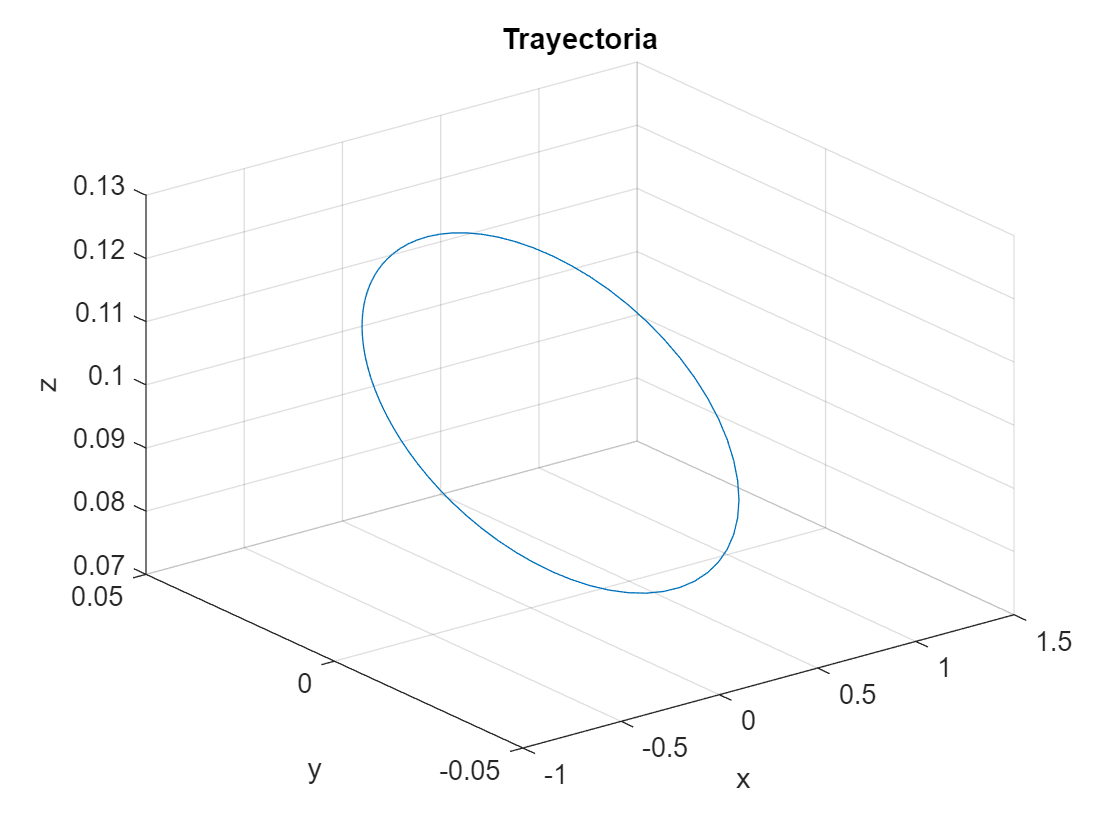

%Parametros de la trayectoria

%% coordenadas del centro del elipsoide 
xc = 0.0;
yc = 0.0;

%Parámetros del vector de desplazamiento de la trayectoria

xtras = 0.10;
ytras = 0.0;
ztras = 0.1;

%Parametros del elipsoide

Aelip = 0.05;
Belip = 0.025;

%Definición de los parámetros de la trayectoria
t_total_1 = 10;%s
t_in = 0.1; %S
tlinea_1 = 0:t_in:t_total_1;

%Definición de la función de la trayectoria

theta_elip_in = 0;
theta_elip_fin = 2*pi;

theta_elip = theta_elip_in+((10/t_total_1^3)*tlinea_1.^3-(15/t_total_1^4)*tlinea_1.^4+(6/t_total_1^5)*tlinea_1.^5)*(theta_elip_fin-theta_elip_in);

%Definciónde las coordenadas

for i=1:length(tlinea_1)
    xp(i) = xtras;
end


yp = xc+ytras+Aelip*cos(theta_elip);
zp = yc+ztras+Belip*sin(theta_elip);

%%%Gráfica de la trayectoria

plot3(xp,yp,zp)
grid on
title('Trayectoria')
xlabel('x')
ylabel('y')
zlabel('z')